Import point cloud

data = dlmread('points3D.txt');
x_3d = data(:, 2);
y_3d = data(:, 3);
z_3d = data(:, 4);
ptCloud = pointCloud([x_3d, y_3d, z_3d], 'Color', [1, 1, 1]);

Find two-dimensional plane

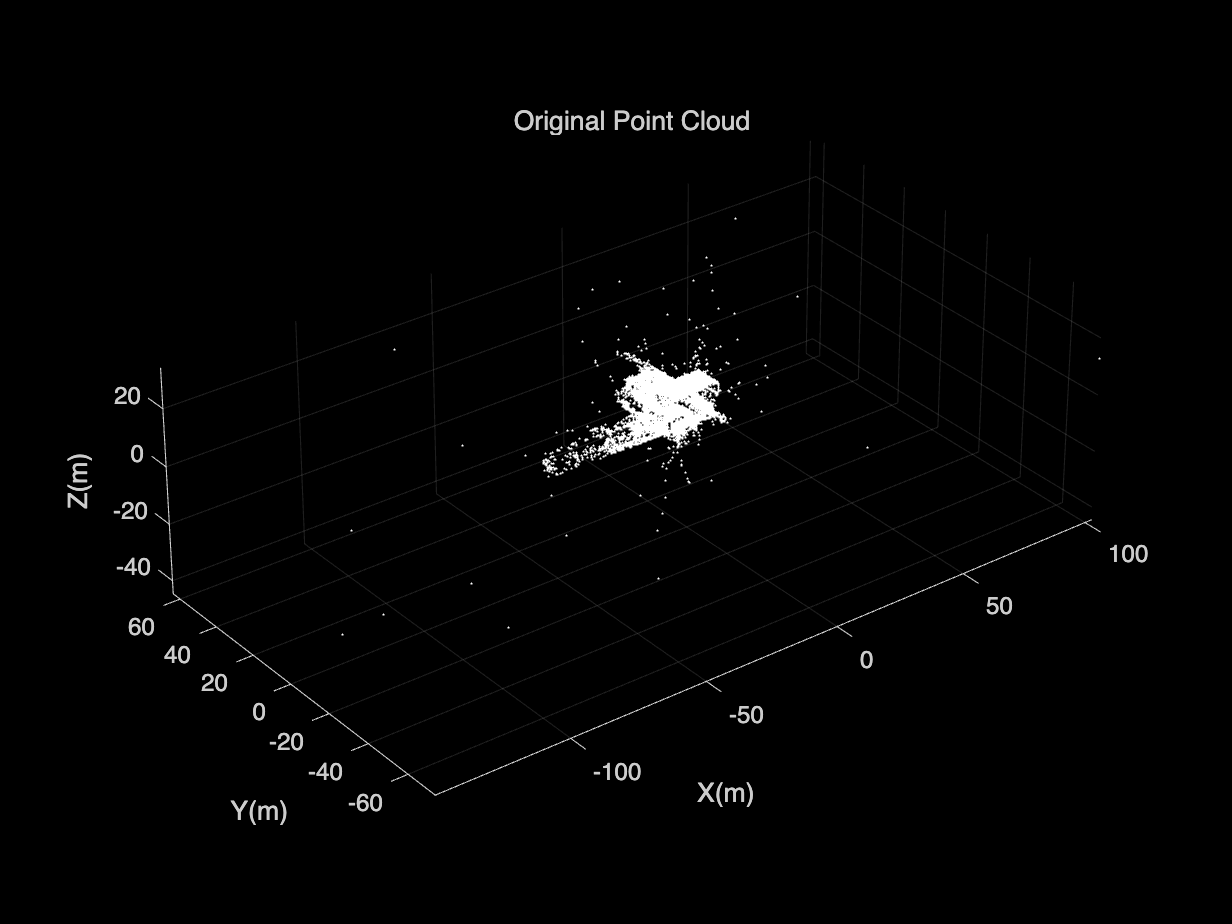

maxDistance = 0.03;
referenceVector_x = [1,0,0];
referenceVector_y = [0,1,0];
referenceVector_z = [0,0,1];
maxAngularDistance = 5;

[model1,inlierIndices_1,outlierIndices_1] = pcfitplane(ptCloud,...
         maxDistance,referenceVector_z,maxAngularDistance);
plane1 = select(ptCloud,inlierIndices_1);

% roi = [-40,14;-5,18;-2,inf];
% sampleIndices = findPointsInROI(ptCloud,roi);
% 
% [model1,inlierIndices,outlierIndices] = pcfitplane(ptCloud,...
%             maxDistance,SampleIndices=sampleIndices);
% plane1 = select(ptCloud,inlierIndices);

figure;
pcshow(ptCloud)
xlabel("X(m)")
ylabel("Y(m)")
zlabel("Z(m)")
title("Original Point Cloud")

figure;
pcshow(plane1.Location,'r');
set(gca,'color','w');
xlabel("X(m)")
ylabel("Y(m)")
zlabel("Z(m)")
title("Plane 1")

'Manually' draw the outline and return the real world coordinates

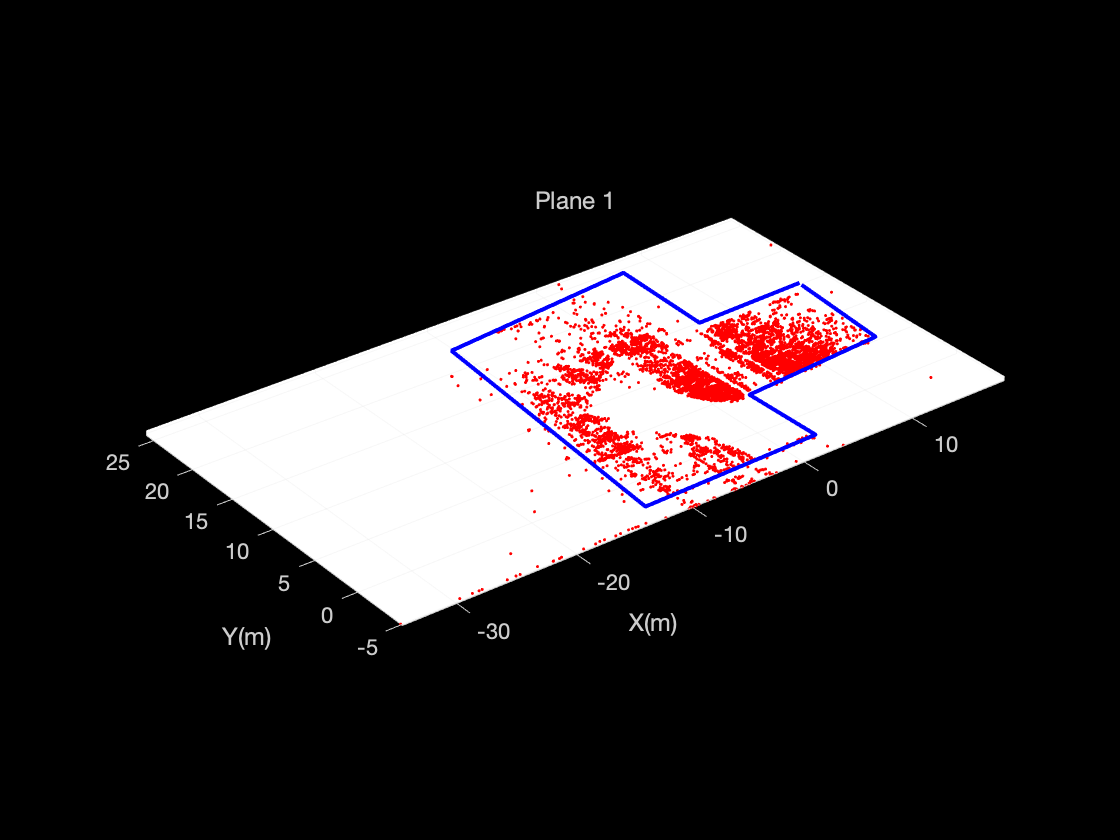

hold on;
% After clicking, you need to press the Enter key
[x_click, y_click] = ginput();
% Draw the Contours
plot(x_click,y_click,'LineWidth',2,'Color','b');
hold off;

% Print real world coordinates
disp('X and Y coordinates of clicked points:');

X and Y coordinates of clicked points:


for i = 1:size(x_click, 1)
    fprintf('Corner Point of Contours %d: X = %.2f, Y = %.2f\n', i, x_click(i), y_click(i));
end

Corner Point of Contours 1: X = 16.17, Y = 14.70
Corner Point of Contours 2: X = 6.35, Y = 14.44
Corner Point of Contours 3: X = 6.70, Y = 23.96
Corner Point of Contours 4: X = -10.60, Y = 22.14
Corner Point of Contours 5: X = -12.89, Y = -3.56
Corner Point of Contours 6: X = 2.61, Y = -3.20
Corner Point of Contours 7: X = 2.52, Y = 3.99
Corner Point of Contours 8: X = 15.24, Y = 4.95
Corner Point of Contours 9: X = 16.09, Y = 14.37


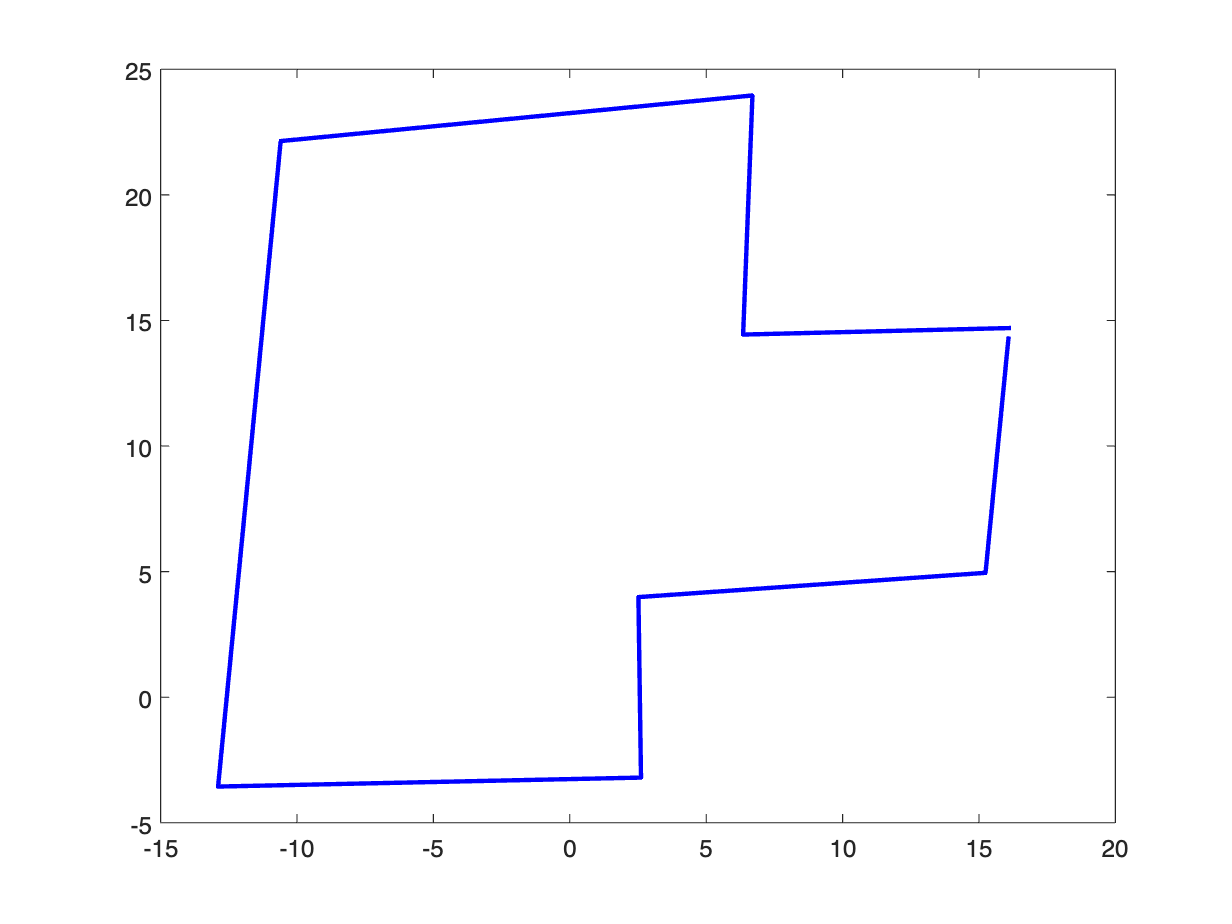

figure;
plot(x_click,y_click,'LineWidth',2,'Color','b');

'Automatically' draws the outline and returns the real world coordinates(with Rotating Calipers Algorithm)

% Gets the coordinates of points on the plane
points = plane1.Location;

% Use PCA convert 3D points to 2D points
[coeff, score] = pca(points);
points2d = points * coeff(:,1:2);

% Compute convex hull
K = convhull(points2d);

% Convex hull vertex
hullPoints = points2d(K, :);

hullPoints =     2.2808   -5.7666
   14.0536   -5.1440
   20.0745    7.9511
   23.3683   15.9689
    8.3510   24.6503
   -0.2744   23.7982
   -7.3035   22.0368
  -34.5965    3.5824
  -10.6657   -2.6160
    2.2808   -5.7666


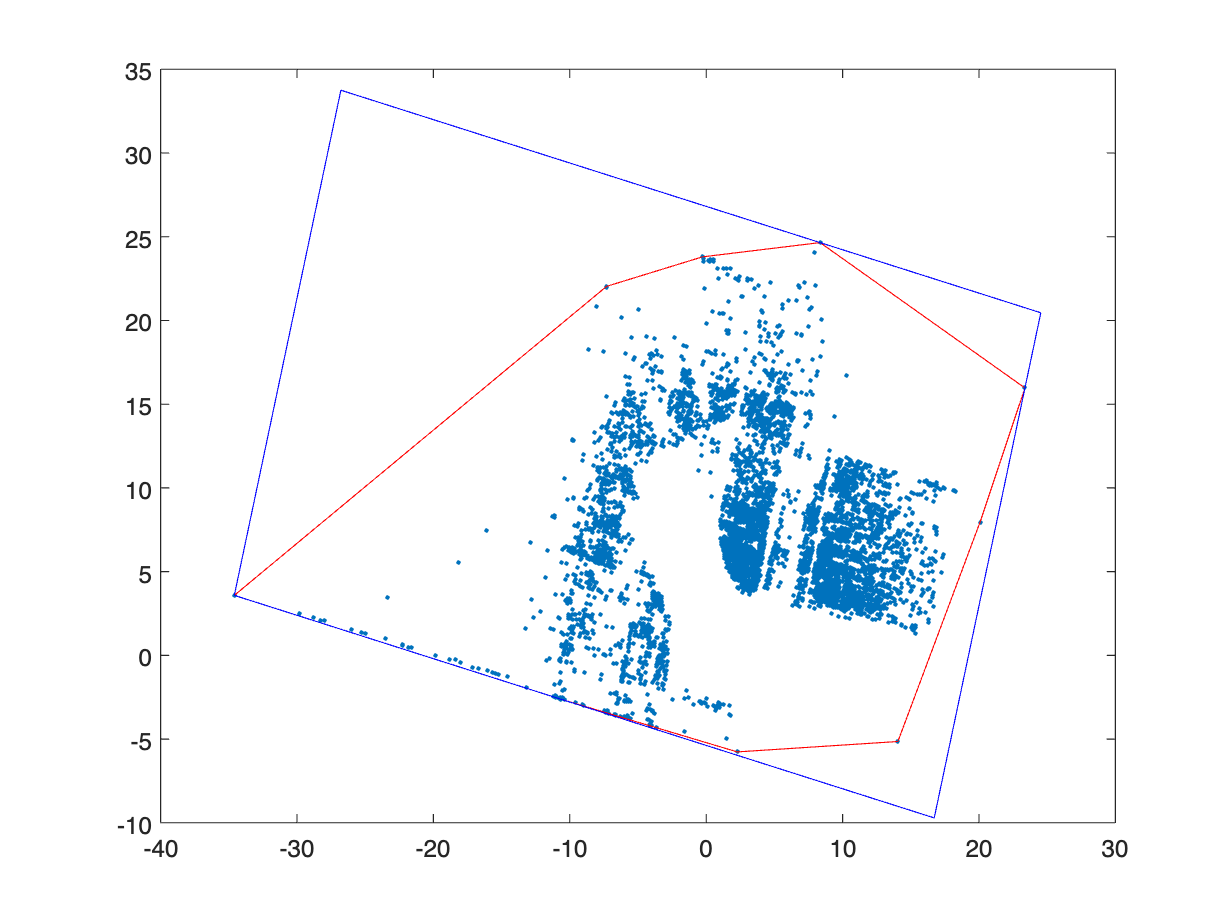



% Initialize minimum area as infinity
minArea = Inf;

for i = 1:size(hullPoints, 1)
    % Take two consecutive vertices as reference edge
    p1 = hullPoints(i, :);
    p2 = hullPoints(mod(i, size(hullPoints, 1)) + 1, :);
    
    % Calculate the direction of these two points
    theta = atan2(p2(2) - p1(2), p2(1) - p1(1));
    
    % Rotate the convex hull vertices
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotatedPoints = (R' * hullPoints')';
    
    % Calculate the bounding rectangle of the points after rotation
    minRotatedX = min(rotatedPoints(:, 1));
    maxRotatedX = max(rotatedPoints(:, 1));
    minRotatedY = min(rotatedPoints(:, 2));
    maxRotatedY = max(rotatedPoints(:, 2));
    
    % Calculate the area
    area = (maxRotatedX - minRotatedX) * (maxRotatedY - minRotatedY);
    
    % If the area is smaller, then update the minimum area and the corresponding transformation matrix
    if area < minArea
        minArea = area;
        minBox = [minRotatedX, maxRotatedX, minRotatedY, maxRotatedY];
        minR = R;
    end
end

% Draw the result through the four corner points of the minimum area rectangle
minBoxCorners = [minBox(1), minBox(3);
                 minBox(1), minBox(4);
                 minBox(2), minBox(4);
                 minBox(2), minBox(3);
                 minBox(1), minBox(3)];
minBoxCorners = (minR * minBoxCorners')';

% Draw the results
figure;
plot(points2d(:,1), points2d(:,2), '.');
hold on;
plot(hullPoints(:,1), hullPoints(:,2), 'r-');
plot(minBoxCorners(:,1), minBoxCorners(:,2), 'b-');
hold off;

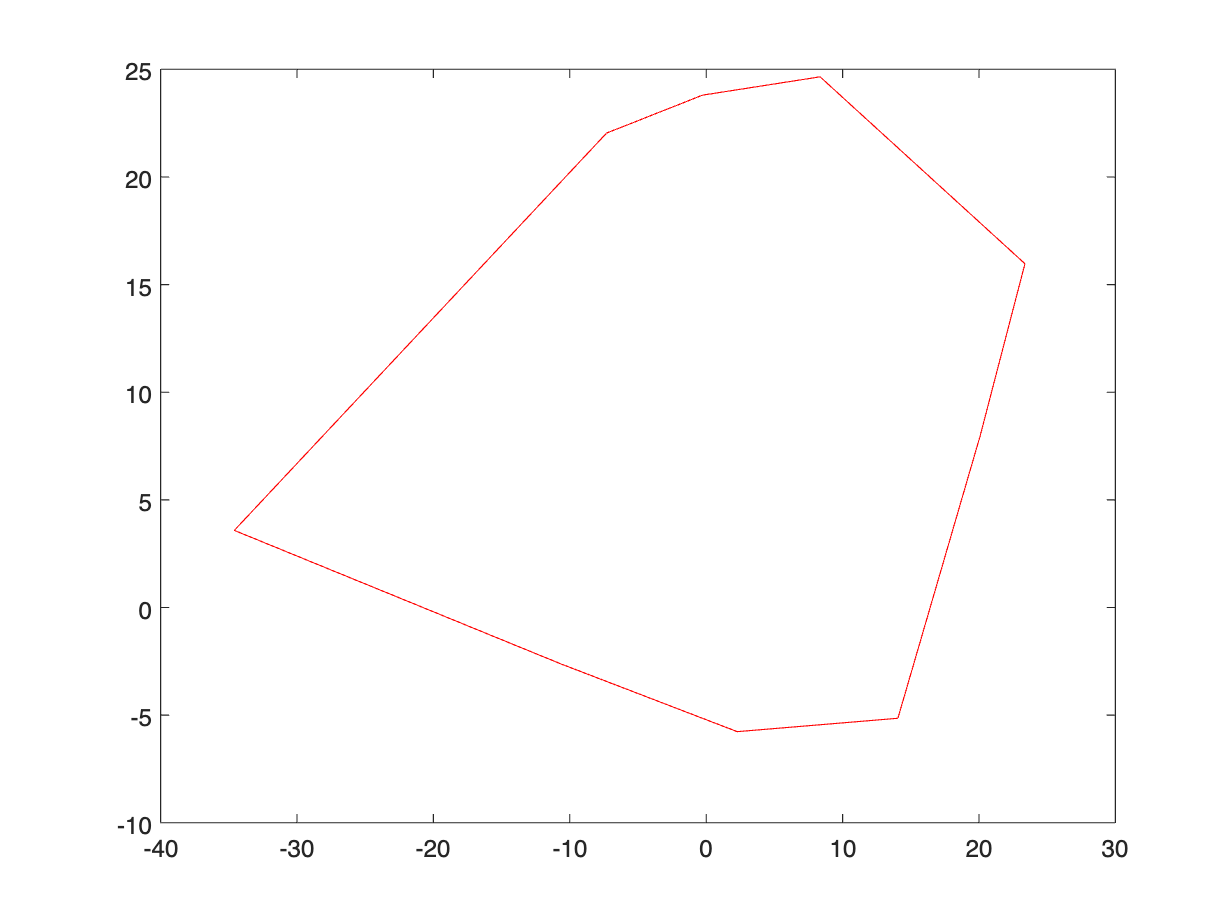


figure;
plot(hullPoints(:,1), hullPoints(:,2), 'r-');


% Find the three-dimensional coordinates of the convex envelope points
hullPoints3D = zeros(size(hullPoints, 1), 3);

for i = 1:size(hullPoints, 1)
    % Find the original 3D point that is closest to the current 2D convex envelope point
    [~, idx] = min(sum((points2d - hullPoints(i, :)).^2, 2));
    
    % Stores the coordinates of the 3D point
    hullPoints3D(i, :) = points(idx, :);
end

% Print 3D convex hull vertex coordinates
disp(hullPoints3D);

    3.6159   -5.0380   -0.3652
   14.8831   -1.5685   -0.3640
   17.5354   12.5983   -0.3437
   18.7785   21.1767   -0.3577
    2.0996   25.9416   -0.3434
   -6.0589   23.0156   -0.3490
  -12.4478   19.5962   -0.3580
  -34.4279   -4.9466   -0.3704
   -9.7081   -5.1335   -0.3624
    3.6159   -5.0380   -0.3652

